**Case 123: TEM**

clear;
clc;
mpc = grid_IEEE123;
lambda_base=10.66;

P=mpc.bus(:,3);
N=size(P,1);
% path-branch incidence matrix
branch_info=mpc.branch(:,1:2);

Adjust Bus 114 to front, each add 1;

P=[P(N);P(1:(N-1))];
replace=find(branch_info==114);
branch_info(replace)=0;
branch_info=branch_info+1;

P_bus=P(2:N,:);
R_branch=diag(mpc.branch(:,3));

[H] = gen_path_branch(branch_info,N);
H_modified=H(:,2:N);

**Original Loss Factor Generation**

V_base=1;
p=2.*H_modified'*R_branch*H_modified*P_bus./V_base.^2;

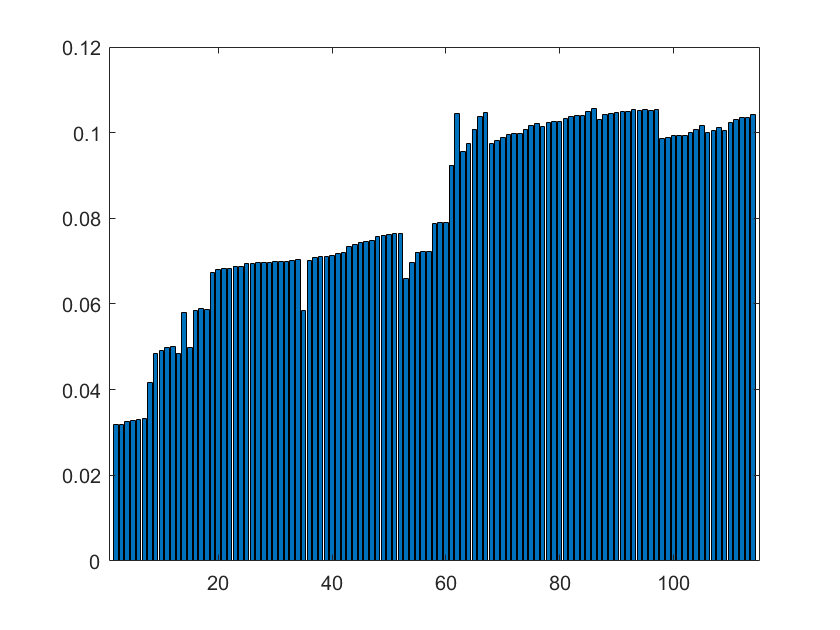

x=2:N;
bar(x,p)

**With DG: with original index applied to P_bus**

G_loc=[6,17,24,28,37,43,55,69,79,107];
G_power=[0.07,0.05,0.09,0.20,0.07,0.30,0.13,0.20,0.09,0.12];

P_bus_new=P_bus;
for i=1:size(G_loc,2)
    loc=G_loc(i);
    power=G_power(i);
    P_bus_new(loc)= P_bus(loc)-power;
end
LFP_new=2.*H_modified'*R_branch*H_modified*P_bus_new./V_base.^2;
for i=1:size(G_loc,2)
    loc=G_loc(i);
    disp(loc)
    disp(LFP_new(loc))
end

     6



    0.0196



    17



    0.0359



    24



    0.0388



    28



    0.0395



    37



    0.0410



    43



    0.0391



    55



    0.0459



    69



    0.0642



    79



    0.0696



   107



    0.0655



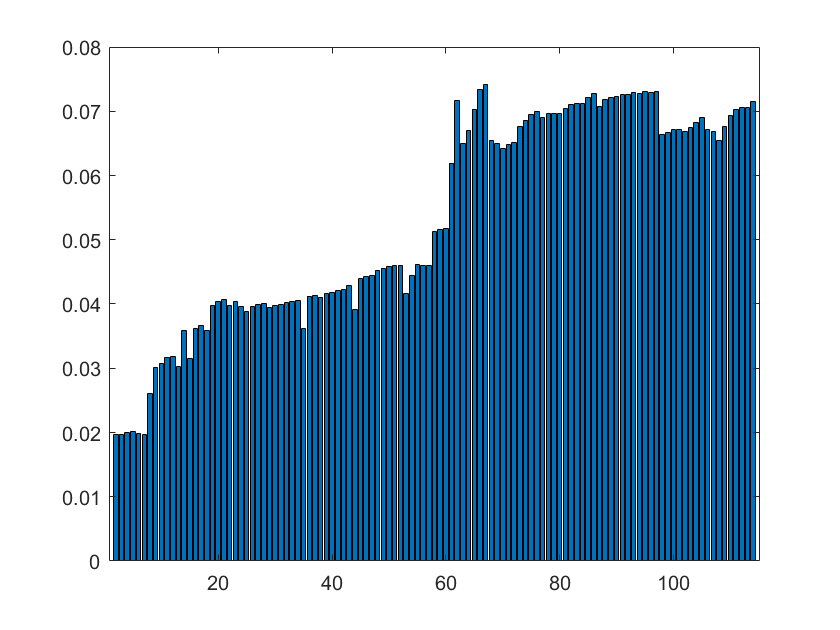

figure
bar(x,LFP_new)

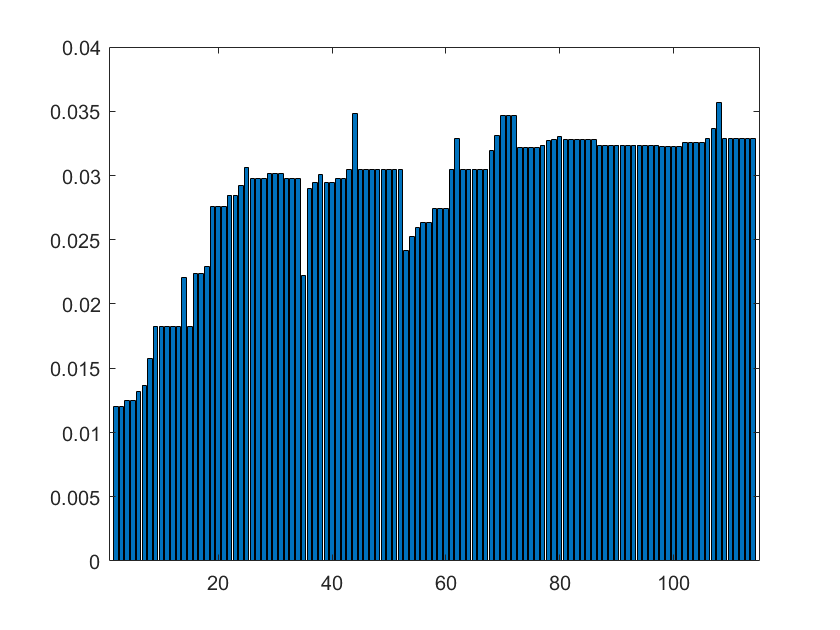

figure
bar(x,p-LFP_new)

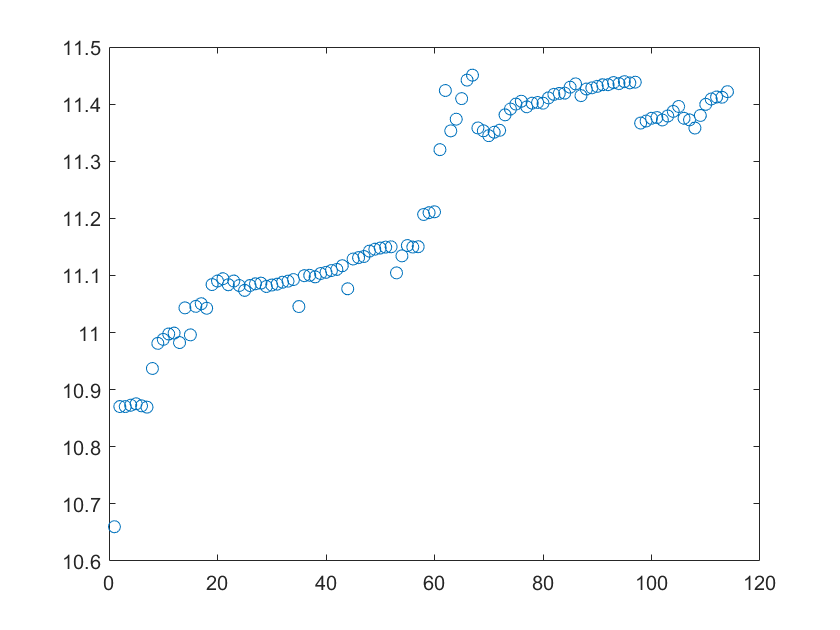

figure
LMP_all=(1+[0;LFP_new])*lambda_base;
plot(1:N,LMP_all,'o')

**Supplier Bidding**

ini_bid=zeros(size(G_loc,2),1);
for i=1:size(G_loc,2)
    loc=G_loc(i);
    ini_bid(i)=LMP_all(loc);
end

[ini_bid_sort, order]=sort(ini_bid);
display(order)

order =      1
     2
     3
     4
     5
     6
     7
     8
    10
     9


C_PRICE_RECORD=[];
ORI_S_PRICE_RECORD=[];
ORI_C_PRICE_RECORD=[];
AMOUNT_RECORD=[];
CURVE_AREA_RECORD=[];
SURPLUS_RECORD=[];

M=size(branch_info,1);
incidence=zeros(N,1);
branch_start=zeros(N,1);
for i=1:M
    s=branch_info(i,1);
    e=branch_info(i,2);
    incidence(e)=s;
    branch_start(s)=i;
end

## **MARKET CLEARING**

**TEM 1: 6-16 branch 0.001**

loc=G_loc(order(1));
surplus=G_power(order(1))-P_bus(loc);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

     6



disp(surplus)

    0.0300



disp(G_price)

   10.8694



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];
A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
H=1;
LMP_ori=LMP_all(17);
for xx=incre:incre:P_bus(16)
    P_loc=xx;
    R_branch=0.001;
    LFP_new=H'*R_branch*H*P_loc./V_base.^2;
    A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
    add_load_unit=add_load_unit+1;
    loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
    loss_record=[loss_record,loss];
end
xx=1:add_load_unit;
xx_new=xx*incre+loss_record;
index=find(xx_new>surplus,1)-1;
final_price=(A_lambda_max(index)+G_price)/2;
mark_loc=A_lambda_max(index);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=surplus;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
xx_new_modi=zeros(index+1,1);
xx_new_modi(1)=xx_new(1);
xx_new_modi(index+1)=surplus-xx_new(index);
for ss=2:index
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area=A_lambda_max(1:index+1)*xx_new_modi-amount*G_price;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   10.9598



disp(mark_loc)

   11.0502



disp(amount)

    0.0300



**TEM 2: 17-96-95 branch 0.001**

loc=G_loc(order(2));
surplus=G_power(order(2))-P_bus(loc);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

    17



disp(surplus)

    0.0300



disp(G_price)

   11.0426



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
branch_needed=0.001;
k=0;
P=[];
LMP_ori=[];
unit_break=[0];
for ii=96:-1:95
    k=k+1;
    loc=ii;
    P=[P;P_bus(loc)];
    P_loc=P;
    if k>1
        b_loc=branch_start(loc+1);
        branch_needed=[branch_needed,mpc.branch(b_loc,3)];
    end
    R_branch=diag(branch_needed);
    H=triu(ones(k));
    LMP_ori=[LMP_ori;LMP_all(loc+1)];
    for xx=incre:incre:P_bus(loc)
        P_loc(k)=xx;
        LFP_new=H'*R_branch*H*P_loc./V_base.^2;
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
        loss_record=[loss_record,loss];
        
    end
    unit_break=[unit_break,add_load_unit];
end
xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj)+1:unit_break(jj+1)];
end
xx=xx*incre+loss_record;
xx_new=xx;
index=find(xx_new>surplus,1)-1;
final_price=(A_lambda_max(index+1)+G_price)/2;
mark_loc=A_lambda_max(index+1);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=surplus;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
xx_new_modi=zeros(index+1,1);
xx_new_modi(1)=xx_new(1);
xx_new_modi(index+1)=surplus-xx_new(index);
for ss=2:index
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area=A_lambda_max(1:index+1)*xx_new_modi-amount*G_price;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.2396



disp(mark_loc)

   11.4365



disp(amount)

    0.0300



**TEM 3: **

**24-27-33 branch 0.001**

loc=G_loc(order(3));
surplus=G_power(order(3))-P_bus(loc);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

    24



disp(surplus)

    0.0500



disp(G_price)

   11.0739



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
H=1;
LMP_ori=LMP_all(34);
for xx=incre:incre:P_bus(33)
    P_loc=xx;
    R_branch=0.001+mpc.branch(branch_start(28),3);
    LFP_new=H'*R_branch*H*P_loc./V_base.^2;
    A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
    add_load_unit=add_load_unit+1;
    loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
    loss_record=[loss_record,loss];
end
xx=1:add_load_unit;
xx_new=xx*incre+loss_record;
index=find(xx_new>surplus,1)-1;
if size(index,2)==0
    index=size(xx_new,2);
end
final_price=(A_lambda_max(index)+G_price)/2;
mark_loc=A_lambda_max(index);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=xx_new(index);
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
xx_new_modi=zeros(index,1);
xx_new_modi(1)=xx_new(1);
for ss=2:index
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area=A_lambda_max(1:index)*xx_new_modi-amount*G_price;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.0815



disp(mark_loc)

   11.0891



disp(amount)

    0.0400



**TEM 4: **

**28-48 branch 0.001**

loc=G_loc(order(4));
surplus=G_power(order(4))-P_bus(loc)-P_bus(loc+1)-P_bus(loc+2);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

    28



disp(surplus)

    0.0800



disp(G_price)

   11.0806



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
H=1;
LMP_ori=LMP_all(49);
for xx=incre:incre:P_bus(48)
    P_loc=xx;
    R_branch=0.001;
    LFP_new=H'*R_branch*H*P_loc./V_base.^2;
    A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
    add_load_unit=add_load_unit+1;
    loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
    loss_record=[loss_record,loss];
end
xx=1:add_load_unit;
xx_new=xx*incre+loss_record;
index=find(xx_new>surplus,1)-1;
if size(index,2)==0
    index=size(xx_new,2);
end
final_price=(A_lambda_max(index)+G_price)/2;
mark_loc=A_lambda_max(index);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=surplus;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
xx_new_modi=zeros(index+1,1);
xx_new_modi(1)=xx_new(1);
xx_new_modi(index+1)=surplus-xx_new(index);
for ss=2:index
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area=A_lambda_max(1:index+1)*xx_new_modi-amount*G_price;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.1129



disp(mark_loc)

   11.1451



disp(amount)

    0.0800



**TEM 5: 37-59-58 branch 0.001**

loc=G_loc(order(5));
surplus=G_power(order(5))-P_bus(loc);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

    37



disp(surplus)

    0.0300



disp(G_price)

   11.0975



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
branch_needed=0.001;
k=0;
P=[];
LMP_ori=[];
unit_break=[0];
for ii=59:-1:58
    k=k+1;
    loc=ii;
    P=[P;P_bus(loc)];
    P_loc=P;
    if k>1
        b_loc=branch_start(loc+1);
        branch_needed=[branch_needed,mpc.branch(b_loc,3)];
    end
    R_branch=diag(branch_needed);
    H=triu(ones(k));
    LMP_ori=[LMP_ori;LMP_all(loc+1)];
    for xx=incre:incre:P_bus(loc)
        P_loc(k)=xx;
        LFP_new=H'*R_branch*H*P_loc./V_base.^2;
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
        loss_record=[loss_record,loss];
    end
    unit_break=[unit_break,add_load_unit];
end
xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj)+1:unit_break(jj+1)];
end
xx=xx*incre+loss_record;
xx_new=xx;
index=find(xx_new>surplus,1)-1;
final_price=(A_lambda_max(index)+G_price)/2;
mark_loc=A_lambda_max(index);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=surplus;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
xx_new_modi=zeros(index+1,1);
xx_new_modi(1)=xx_new(1);
xx_new_modi(index+1)=surplus-xx_new(index);
for ss=2:index
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area=A_lambda_max(1:index+1)*xx_new_modi-amount*G_price;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.1534



disp(mark_loc)

   11.2092



disp(amount)

    0.0300



**TEM 6: 43**

loc=G_loc(order(6));
surplus=G_power(order(6))-P_bus(loc);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

    43



disp(surplus)

    0.2600



disp(G_price)

   11.0767



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

**path 1: 46-45 branch 0.001**

A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
branch_needed=0.001;
k=0;
P=[];
LMP_ori=[];
unit_break=[0];
for ii=46:-1:45
    k=k+1;
    loc=ii;
    P=[P;P_bus(loc)];
    P_loc=P;
    if k>1
        b_loc=branch_start(loc+1);
        branch_needed=[branch_needed,mpc.branch(b_loc,3)];
    end
    R_branch=diag(branch_needed);
    H=triu(ones(k));
    LMP_ori=[LMP_ori;LMP_all(loc+1)];
    for xx=incre:incre:P_bus(loc)
        P_loc(k)=xx;
        LFP_new=H'*R_branch*H*P_loc./V_base.^2;
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
        loss_record=[loss_record,loss];
    end
    unit_break=[unit_break,add_load_unit];
end
xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj)+1:unit_break(jj+1)];
end
xx=xx*incre+loss_record;
xx_new=xx;
xx_new_1=xx_new;
A_lambda_max_1=A_lambda_max;

**path 2: 65-66-64 branch 0.001**

H=triu(ones(2));
P=P_bus(65:66,:);
LMP_ori=LMP_all(66:67,:);
P_loc=P;
branch_needed=[0.001,mpc.branch(branch_start(65),3)];
R_branch=diag(branch_needed);
LFP_new=H'*R_branch*H*P_loc./V_base.^2;
loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
P_base=sum(P);
xx_pre=0:incre:P_base+loss;
A_lambda_max=ones(1, size(xx_pre,2))*min(LMP_ori./(1+LFP_new));
A_lambda_max_pre=A_lambda_max;
mark_x=P_base+loss;
mark_y=min(LMP_ori./(1+LFP_new));

loss_record=[];
incre=0.0001;
add_load_unit=0;
k=0;
unit_break=[0];
for ii=64:-1:62
    k=k+1;
    loc=ii;
    b_loc=branch_start(loc+1);
    branch_needed=[branch_needed,mpc.branch(b_loc,3)];
    R_branch=diag(branch_needed);
    P=[P;P_bus(loc)];
    P_loc=P;
    H=[H;zeros(1,k+1)];
    H=[H zeros(k+2,1)];
    H(1,k+2)=1;
    for mm=3:k+2
        H(mm,k+2)=1;
    end
    LMP_ori=[LMP_ori;LMP_all(loc+1)];
    for xx=incre:incre:P_bus(loc)
        P_loc(k)=xx;
        LFP_new=H'*R_branch*H*P_loc./V_base.^2;
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
        loss_record=[loss_record,loss];
    end
    unit_break=[unit_break,add_load_unit];
    mark_x=[mark_x,P_base+(add_load_unit)*incre+loss];
    mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
end
xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj)+1:unit_break(jj+1)];
end
xx=P_base+xx*incre+loss_record;
xx_new=[xx_pre,xx];
xx_new_2=xx_new;
A_lambda_max_2=A_lambda_max;

**Horizontally Concatenate**

A_lambda_all=[A_lambda_max_1,A_lambda_max_2];
max_Y=max(A_lambda_all);
min_Y=min(A_lambda_all);
A_lambda_max_1_a=[A_lambda_max_1,0];
A_lambda_max_2_a=[A_lambda_max_2,0];
xx_new_1_a=[0,xx_new_1];
xx_new_2_a=[0,xx_new_2];
xx_all=[];
for y_point=max_Y:-0.001:min_Y
    index_1=find(A_lambda_max_1_a<y_point,1);
    index_2=find(A_lambda_max_2_a<y_point,1);
    xx_all=[xx_all,xx_new_1_a(index_1)+xx_new_2_a(index_2)];
end

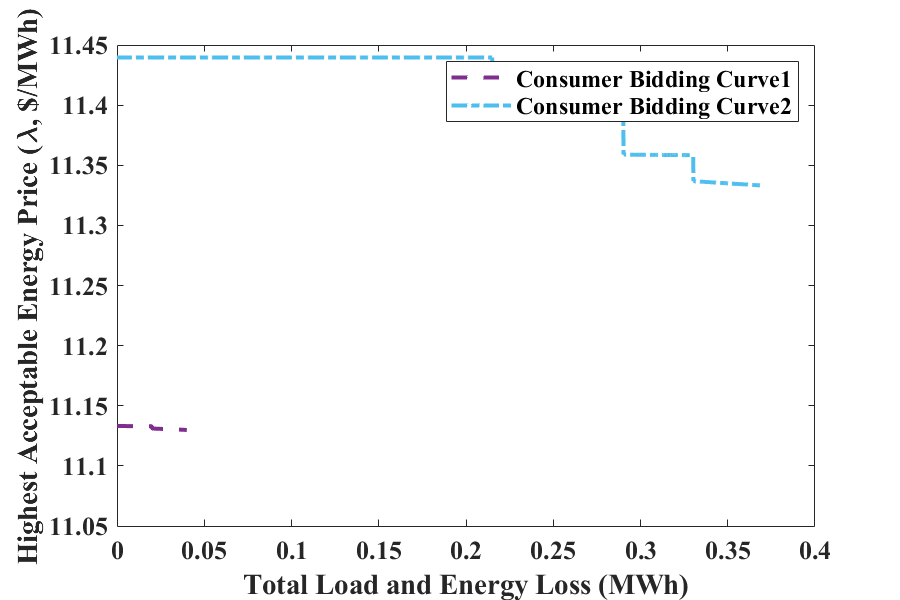

A_lambda_all=max_Y:-0.001:min_Y;
figure
plot(xx_new_1,A_lambda_max_1,'--','LineWidth',2,'Color',[0.4940, 0.1840, 0.5560])
hold on
plot(xx_new_2,A_lambda_max_2,'-.','LineWidth',2,'Color',[0.3010, 0.7450, 0.9330])
ylim([round(G_price,1)-0.05, round(max_Y,1)+0.05])
legend('Consumer Bidding Curve1','Consumer Bidding Curve2','FontSize',12,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Total Load and Energy Loss (MWh)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
ylabel('Highest Acceptable Energy Price (\lambda, $/MWh)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 600 400]);
set(gca,'FontSize',13,'FontName','Times New Roman','FontWeight','Bold')

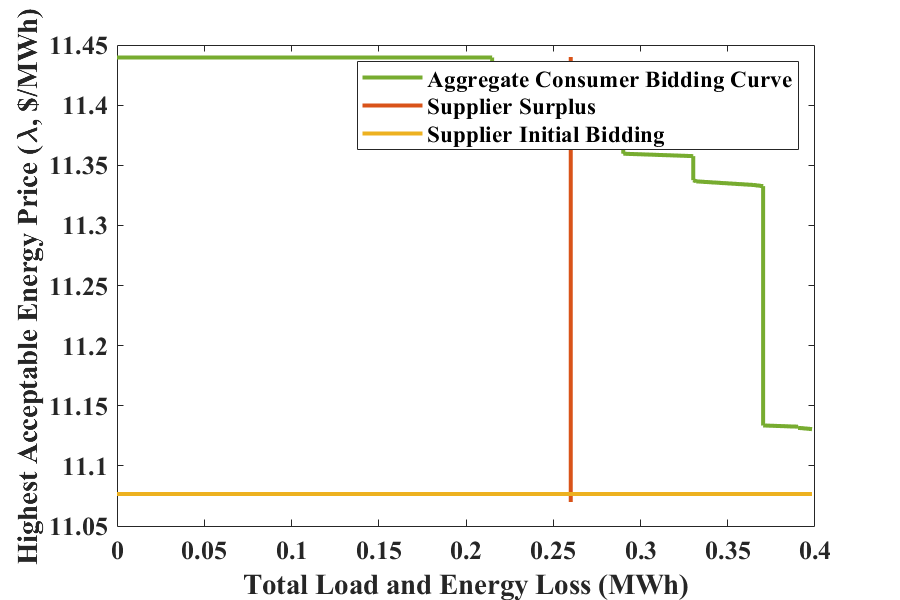

figure

xx_all=[xx_pre,xx_all];
A_lambda_all=[A_lambda_max_pre,A_lambda_all];
y_hor=(round(G_price,2))-0.01:0.01:round(max_Y,2);
x_hor=ones(1, size(y_hor,2))*surplus;
y_min=ones(1,size(xx_all,2))*G_price;

plot(xx_all,A_lambda_all,'LineWidth',2,'Color',[0.4660, 0.6740, 0.1880])
hold on 
plot(x_hor,y_hor,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980])
hold on 
plot(xx_all, y_min,'LineWidth',2,'Color',[0.9290, 0.6940, 0.1250])
ylim([round(G_price,1)-0.05, round(max_Y,1)+0.05])
legend('Aggregate Consumer Bidding Curve','Supplier Surplus','Supplier Initial Bidding')
xlabel('Total Load and Energy Loss (MWh)')
ylabel('Highest Acceptable Energy Price (\lambda, $/MWh)')
set(gcf,'Position',[100 100 600 400]);
set(gca,'FontSize',13,'FontName','Times New Roman','FontWeight','Bold')

index=find(xx_all>surplus,1);
final_price=(A_lambda_all(index)+G_price)/2;
mark_loc=A_lambda_all(index);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
index_1=find(A_lambda_max_1<mark_loc,1);
% index_2=find(A_lambda_max_2<mark_loc,1);
index_2=find(xx_new_2>surplus,1);
amount=surplus;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
xx_new_modi=zeros(index_2+1,1);
xx_new_modi(1)=xx_new_2(1);
xx_new_modi(index_2+1)=surplus-xx_new_2(index_2);
for ss=2:index_2
    xx_new_modi(ss)=xx_new_2(ss)-xx_new_2(ss-1);
end
area=A_lambda_max_2(1:index_2+1)*xx_new_modi-amount*G_price;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.2386



disp(mark_loc)

   11.4006



disp(amount)

    0.2600



**TEM 7: 55**

loc=G_loc(order(7));
surplus=G_power(order(7))-P_bus(loc)-P_bus(loc+1);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

    55



disp(surplus)

    0.0900



disp(G_price)

   11.1497



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

**Path 1: 94**

A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
H=1;
LMP_ori=LMP_all(95);
for xx=incre:incre:P_bus(94)
    P_loc=xx;
    R_branch=0.001;
    LFP_new=H'*R_branch*H*P_loc./V_base.^2;
    A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
    add_load_unit=add_load_unit+1;
    loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
    loss_record=[loss_record,loss];
end
xx=1:add_load_unit;
xx_new=xx*incre+loss_record;
index=find(xx_new>surplus,1)-1;
if size(index,2)==0
    index_1=size(xx_new,2);
end
% amount_1=index_1*incre;
% area_1=sum(A_lambda_max(1:index_1))*incre-amount_1*G_price;
amount_1=xx_new(index_1);
xx_new_modi=zeros(index_1,1);
xx_new_modi(1)=xx_new(1);
for ss=2:index_1
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area_1=A_lambda_max(1:index_1)*xx_new_modi-amount_1*G_price;

**Path 2: 92**

A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
H=1;
LMP_ori=LMP_all(93);
for xx=incre:incre:P_bus(92)
    P_loc=xx;
    R_branch=0.001;
    LFP_new=H'*R_branch*H*P_loc./V_base.^2;
    A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
    add_load_unit=add_load_unit+1;
    loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
    loss_record=[loss_record,loss];
end
xx=1:add_load_unit;
xx_new=xx*incre+loss_record;
index=find(xx_new>surplus,1)-1;
if size(index,2)==0
    index_2=size(xx_new,2);
end
% amount_2=index_2*incre;
% area_2=sum(A_lambda_max(1:index_2))*incre-amount_2*G_price;
amount_2=xx_new(index_2);
xx_new_modi=zeros(index_2,1);
xx_new_modi(1)=xx_new(1);
for ss=2:index_2
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area_2=A_lambda_max(1:index_2)*xx_new_modi-amount_2*G_price;

final_price=(A_lambda_max(index_2)+G_price)/2;
mark_loc=A_lambda_max(index_2);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=amount_1+amount_2;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
area=area_1+area_2;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.2935



disp(mark_loc)

   11.4373



disp(amount)

    0.0800



**TEM 8: 69**

loc=G_loc(order(8));
surplus=G_power(order(8))-P_bus(loc)-P_bus(loc+1)-P_bus(loc+2);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

    69



disp(surplus)

    0.1000



disp(G_price)

   11.3447



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

**Path 1: 74 75**

R_branch=diag([0.001,mpc.branch(branch_start(75),3)]);
H=triu(ones(2));
LMP_ori=LMP_all(75:76);
P_loc=[P_bus(74);P_bus(75)];
loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
LFP_new=H'*R_branch*H*P_loc./V_base.^2;
A_lambda_max=min(LMP_ori./(1+LFP_new));
A_lambda_max_1=A_lambda_max;
amount_1=P_bus(74)+P_bus(75)+loss;
area_1=A_lambda_max*amount_1-G_price*amount_1;

**Path 2: 100**

surplus=surplus-amount_1-loss;
A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
H=1;
LMP_ori=LMP_all(101);
for xx=incre:incre:P_bus(100)
    P_loc=xx;
    R_branch=0.001;
    LFP_new=H'*R_branch*H*P_loc./V_base.^2;
    A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
    add_load_unit=add_load_unit+1;
    loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
    loss_record=[loss_record,loss];
end
xx=1:add_load_unit;
xx_new=xx*incre+loss_record;
index_2=find(xx_new>surplus,1)-1;
if size(index_2,2)==0
    index_2=size(xx_new,2);
end
amount_2=xx_new(index_2);
xx_new_modi=zeros(index_2,1);
xx_new_modi(1)=xx_new(1);
for ss=2:index_2
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area_2=A_lambda_max(1:index_2)*xx_new_modi-amount_2*G_price;

final_price=(A_lambda_max(index_2)+G_price)/2;
mark_loc=A_lambda_max(index_2);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=amount_1+amount_2;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
area=area_1+area_2;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.3605



disp(mark_loc)

   11.3762



disp(amount)

    0.0999



**TEM 9: 107**

loc=G_loc(order(9));
surplus=G_power(order(9))-P_bus(loc);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

   107



disp(surplus)

    0.0800



disp(G_price)

   11.3581



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

**Path: 113 61-112**

H=triu(ones(2));
P=P_bus([113,61],:);
LMP_ori=LMP_all([114,62],:);
branch_needed=[0.001,mpc.branch(branch_start(114),3)];
R_branch=diag(branch_needed);
P_loc=P;
LFP_new=H'*R_branch*H*P_loc./V_base.^2;
loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
P_base=sum(P);
xx_pre=0:incre:P_base+loss;
A_lambda_max=ones(1, size(xx_pre,2))*min(LMP_ori./(1+LFP_new));
mark_x=P_base+loss;
mark_y=min(LMP_ori./(1+LFP_new));

loss_record=[];
incre=0.0001;
add_load_unit=0;
k=0;
unit_break=[0];
for ii=112:-1:112
    k=k+1;
    loc=ii;
    b_loc=branch_start(loc+1);
    branch_needed=[branch_needed,mpc.branch(b_loc,3)];
    R_branch=diag(branch_needed);
    P=[P;P_bus(loc)];
    P_loc=P;
    H=[H;zeros(1,k+1)];
    H=[H zeros(k+2,1)];
    H(1,k+2)=1;
    for mm=3:k+2
        H(mm,k+2)=1;
    end
    LMP_ori=[LMP_ori;LMP_all(loc+1)];
    for xx=incre:incre:P_bus(loc)
        P_loc(k)=xx;
        LFP_new=H'*R_branch*H*P_loc./V_base.^2;
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
        loss_record=[loss_record,loss];
    end
    unit_break=[unit_break,add_load_unit];
    mark_x=[mark_x,P_base+(add_load_unit)*incre+loss];
    mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
end
xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj)+1:unit_break(jj+1)];
end
xx=P_base+xx*incre+loss_record;
xx_new=[xx_pre,xx];

index=find(xx_new>surplus,1)-1;
final_price=(A_lambda_max(index)+G_price)/2;
mark_loc=A_lambda_max(index);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=surplus;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
xx_new_modi=zeros(index+1,1);
xx_new_modi(1)=xx_new(1);
xx_new_modi(index+1)=surplus-xx_new(index);
for ss=2:index
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area=A_lambda_max(1:index+1)*xx_new_modi-amount*G_price;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.3839



disp(mark_loc)

   11.4096



disp(amount)

    0.0800



**TEM 10: 79-85-84**

loc=G_loc(order(10));
surplus=G_power(order(10))-P_bus(loc);
SURPLUS_RECORD=[SURPLUS_RECORD,surplus];
G_price=LMP_all(loc+1);
disp(loc)

    79



disp(surplus)

    0.0500



disp(G_price)

   11.4017



ORI_S_PRICE_RECORD=[ORI_S_PRICE_RECORD,G_price];

A_lambda_max=[];
loss_record=[];
incre=0.0001;
add_load_unit=0;
branch_needed=0.001;
k=0;
P=[];
LMP_ori=[];
unit_break=[0];
for ii=85:-1:84
    k=k+1;
    loc=ii;
    P=[P;P_bus(loc)];
    P_loc=P;
    if k>1
        b_loc=branch_start(loc+1);
        branch_needed=[branch_needed,mpc.branch(b_loc,3)];
    end
    R_branch=diag(branch_needed);
    H=triu(ones(k));
    LMP_ori=[LMP_ori;LMP_all(loc+1)];
    for xx=incre:incre:P_bus(loc)
        P_loc(k)=xx;
        LFP_new=H'*R_branch*H*P_loc./V_base.^2;
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H*P_loc)'*R_branch*H*P_loc./V_base.^2;
        loss_record=[loss_record,loss];
        
    end
    unit_break=[unit_break,add_load_unit];
end
xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj)+1:unit_break(jj+1)];
end
xx=xx*incre+loss_record;
xx_new=xx;
index=find(xx_new>surplus,1)-1;
final_price=(A_lambda_max(index+1)+G_price)/2;
mark_loc=A_lambda_max(index+1);
C_PRICE_RECORD=[C_PRICE_RECORD,mark_loc];
amount=surplus;
AMOUNT_RECORD=[AMOUNT_RECORD,amount];
xx_new_modi=zeros(index+1,1);
xx_new_modi(1)=xx_new(1);
xx_new_modi(index+1)=surplus-xx_new(index);
for ss=2:index
    xx_new_modi(ss)=xx_new(ss)-xx_new(ss-1);
end
area=A_lambda_max(1:index+1)*xx_new_modi-amount*G_price;
CURVE_AREA_RECORD=[CURVE_AREA_RECORD,area];
disp(final_price)

   11.4150



disp(mark_loc)

   11.4283



disp(amount)

    0.0500



**WITH TOPOLOGY and LOSS**

disp(C_PRICE_RECORD-ORI_S_PRICE_RECORD)

    0.1807    0.3939    0.0152    0.0644    0.1117    0.3239    0.2875    0.0315    0.0515    0.0266



**WITHOUT TOPOLOGY and LOSS**

[LMP_sort, C_order]=sort(LMP_all,'descend');
C_bus=P_bus;
for k=1:size(C_order,1)-1
%     disp(C_order(k)-1);
    C_bus(k)=P_bus(C_order(k)-1);
end
VIRTUAL_RECORD=[];
k=0;
j=0;
for i=1:10
    surplus=SURPLUS_RECORD(i);
    while surplus>0
        k=k+1;
        if surplus>C_bus(k) && C_bus(k)>0
            surplus=surplus-C_bus(k);
            C_bus(k)=0;
            disp(i)
            disp(C_order(k)-1)
            disp(LMP_all(C_order(k)))
            j=j+1;
        elseif C_bus(k)>0
            C_bus(k)=C_bus(k)-surplus;
            surplus=0;
            disp(i)
            disp(C_order(k)-1)
            disp(LMP_all(C_order(k)))
            VIRTUAL_RECORD=[VIRTUAL_RECORD,LMP_all(C_order(k))];
        end
    end
    k=j;
end

     1



    66



   11.4507



     2



    66



   11.4507



     3



    66



   11.4507



     3



    65



   11.4421



     4



    65



   11.4421



     5



    65



   11.4421



     5



    94



   11.4393



     6



    94



   11.4393



     6



    96



   11.4384



     6



    92



   11.4377



     6



    95



   11.4372



     6



    85



   11.4355



     6



    90



   11.4339



     6



    84



   11.4296



     6



    88



   11.4286



     6



    87



   11.4264



     7



    87



   11.4264



     7



    61



   11.4238



     7



   113



   11.4218



     8



   113



   11.4218



     8



    83



   11.4192



     8



    82



   11.4187



     8



    86



   11.4149



     8



   111



   11.4125



     9



   111



   11.4125



     9



   112



   11.4120



     9



    80



   11.4110



     9



    64



   11.4096



    10



    64



   11.4096



disp(VIRTUAL_RECORD-ORI_S_PRICE_RECORD)

    0.5813    0.4081    0.3682    0.3614    0.3418    0.3498    0.2721    0.0678    0.0515    0.0080



**Welfare Allocation**

eta_all=0:0.001:1;
eta_num=size(eta_all,2);
S_WELFARE=zeros(1,eta_num);
C_WELFARE=zeros(1,eta_num);
for ss=1:eta_num
    eta=eta_all(ss);
    final_price=eta*ORI_S_PRICE_RECORD+(1-eta)*C_PRICE_RECORD;
    welfare_supplier=(final_price-ORI_S_PRICE_RECORD).*AMOUNT_RECORD;
    welfare_customer=CURVE_AREA_RECORD-welfare_supplier;
    S_WELFARE(ss)=sum(welfare_supplier)*24*365*1000/(10^6);
    C_WELFARE(ss)=sum(welfare_customer)*24*365*1000/(10^6);
end

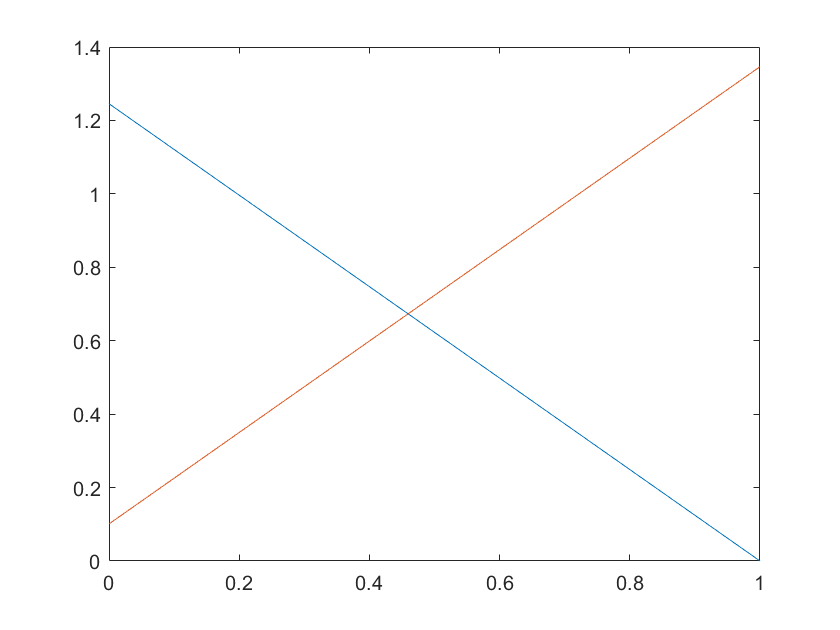

figure
plot(eta_all,S_WELFARE)
hold on
plot(eta_all,C_WELFARE)

figure
barbar=bar(eta_all,[S_WELFARE;C_WELFARE]','stacked')

barbar =   1×2 Bar 数组:

    Bar    Bar


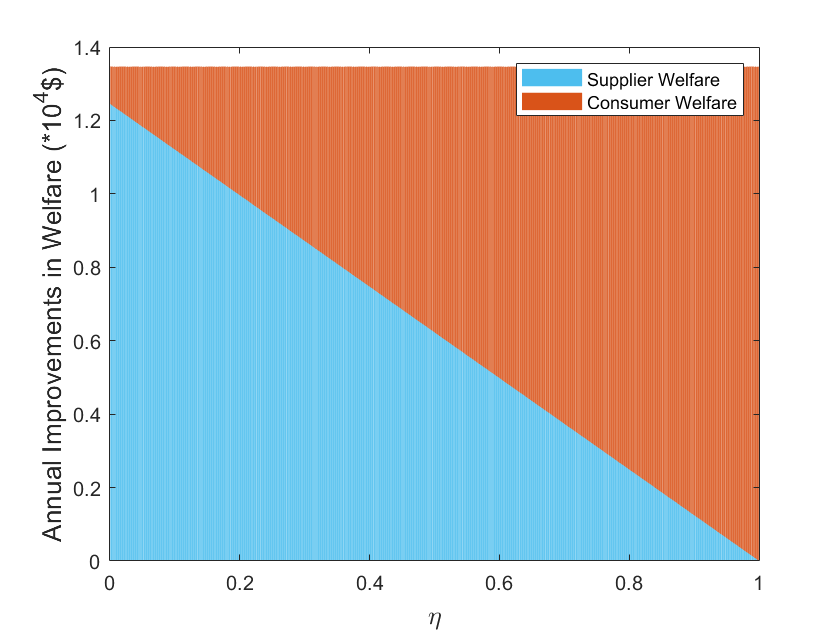

% bar(y,'FaceColor',[0 .5 .5],'EdgeColor',[0 .9 .9],'LineWidth',1.5)
barbar(1).FaceColor = [0.3010, 0.7450, 0.9330];
barbar(1).LineWidth=0.01;
barbar(2).FaceColor = [0.8500, 0.3250, 0.0980];
barbar(2).LineWidth=0.01;
xlabel('\eta','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
ylabel('Annual Improvements in Welfare (*10^4$)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
legend('Supplier Welfare','Consumer Welfare')

sum(G_power)/sum(P_bus)

ans = 0.3782